# Framework for a Multiuser MISO with Iterative Detection and Decoding (IDD), incorporating Reflective Intelligent Surfaces (RIS).

# **With Parallel Loop**

`The code was employed to generate the results presented in the paper: Iterative Detection and Decoding for RIS-Assisted Multiuser Multiple-Antenna Systems`

**Author:** Roberto Câmara (camara2k@gmail.com/ camara@ime.eb.br)

**Project Start Date:** Fev/2024

## Introduction to the Code:

This code is designed to conduct testing in a specific scenario involving the positioning of users, access points (AP), using the Rayleigh channel model with low LOS signal. The primary goal is to assess whether increasing the number of iterations in the Iterative Detection and Decoding (IDD) process enhances performance.

Key Features of this Code:

- Automatic saving for each SNR iteration.

Observation:

- Ideal number of Packets: 1500~2000. (at least)

clear; close all; clc
% Define if the simulation will be run in parallel-------------------------------
% It is also needed to manually change the inner loop 'for' to 'parfor'!
useParallel = false; 
% Progress bar ------------------------------------------------------------------
if ~useParallel
    f = waitbar(0, 'Starting');
end

### Setup variables

format long
% addpath('ldpc','functions','data','optimization')
warning('off')

% Simulation --------------------------------------------------------------
Packets = 50;                             % Number of Packets to Send
Pw_user_dBm = 1:1:8;                        % Power per user in dBm
sigma_n2_dbm = -100;                        % Noise in dBm

% Active RIS parameters ---------------------------------------------------
active.pwr_div = 1;
active.noise = 10^(-100/10); %in mW

% System ------------------------------------------------------------------
QAM_M = 4;                                  % Order of the modulation
numPWR = length(Pw_user_dBm);               % Aux variable
sys.n_tx = 12;                              % Number of Transmit Antennas
sys.n_rx = 32;                              % Number of Receive Antennas
sys.Nc = 64;                                % Number of RIS cells
sys.M_ORD = log2(QAM_M);                    % Order of the modulation
sys.sigma_n2_mW = 10^(sigma_n2_dbm/10);     % Noise power in mW
sys.PWR = 10.^(Pw_user_dBm/10);             % Signal power in mW
%sys.PacketDataLength = 256                 % Defined in the ldpc
iterAO = 5;                                % Iterations to convergence of Φ and W

% Channel estimation -----------------------------------------------------------------
% Values chosen based on the block length (512)
estimation.T0_min = sys.n_tx*2+4; % minimum number of training symbols in the first stage
estimation.T1_min = sys.Nc+19; % minimum number of training symbols in the second stage
estimation.noise_dbm = -125; %dBm

% Fading and users positions ---------------------------------------------------------
large_fading_1 = 2.2;
large_fading_2 = 2.8;
enviroment.PLs = @(dis) (10^(-3.73))./(dis.^large_fading_1); % PLs = 37.3+ 22.0 logd, %strong signal
enviroment.PLw = @(dis) (10^(-4.12))./(dis.^large_fading_2);  % PLw = 41.2+ 28.7 logd, %weak signal 
enviroment.kappa = 1;
enviroment.pos_ap  = [0; 0; 0];
enviroment.pos_ris = [400; 10; 0];
enviroment.pos_center_users = [400; 0; 0];
enviroment.radius_users = 5;

% LDPC Parameters A-(Parity), G-(Generator)-------------------------------
load channel_matrix_camara;                                 % Load design_gallager_256-128;
[M,idd.N] = size(A_LDPC);                                   % Don't confuse K with k
K = idd.N-M;
idd.A = A_LDPC;
idd.G = G_LDPC;
idd.R = K/idd.N;                                            % Data rate
idd.iter = 10;                                              % Number of iterations in LDPC
idd.IDD = 1;                                                % IDD iterations
DecimalPacketCodeWord = (0:QAM_M-1)';
idd.S_matrix = qammod(DecimalPacketCodeWord',QAM_M,'gray').'/sqrt(2);
sys.PacketDataLength = K;                                   % Length of data of each packet
% 3 iterations idd
idd3 = idd;
idd3.IDD = 3;

% Methods implemented ----------------------------
methods = [ 
            "MMSE W/O RIS Perfect CSI";
            "IDD (1) MMSE W/O RIS Perfect CSI";
            "IDD (3) MMSE W/O RIS Perfect CSI";
          ];

% Auxiliar variables ------------------------------
PacketBitLength = sys.PacketDataLength*sys.n_tx;
numberofmethods = length(methods);
RsumVec = zeros(numPWR,Packets,numberofmethods);               
BerVec  = zeros(numPWR,Packets,numberofmethods);
DateI = datetime('now');


### **Main Function **

for pwr = 1:numPWR
    disp(numPWR-pwr)
    for NumPackets = 1:Packets
        % init variables ---------------------------------------------------
        Ber = zeros(length(methods),1);
        Rsum = zeros(length(methods),1);
        % Channel coefficients generation ----------------------------------------------------------------------------
        channel = generateRayleight(sys,enviroment,'weak'); 
        % MMSE W/O RIS Perfect CSI----------------------------------------------------------------------------------------------
        [bErrors, Rsum_aux] = mmseWOris(sys, channel, pwr);
        Ber(1) = bErrors/(PacketBitLength);
        Rsum(1) = Rsum_aux;
        % % % IDD (1) W/O RIS Estimated CSI----------------------------------------------------------------------------------------------
        [bErrors, Rsum_aux] = iddWOris(sys,channel,idd,pwr);
        Ber(2) = bErrors/(PacketBitLength);
        Rsum(2) = Rsum_aux;
        % % IDD (3) W/O RIS Estimated CSI----------------------------------------------------------------------------------------------
        [bErrors, Rsum_aux] = iddWOris(sys,channel,idd3,pwr);
        Ber(3) = bErrors/(PacketBitLength);
        Rsum(3) = Rsum_aux;    

        %Ber and Sum-rate Matrix generation
        BerVec(pwr,NumPackets,:) = Ber;
        RsumVec(pwr,NumPackets,:) = Rsum;

        % Wait bar -----------------------------------------------------------------
        if ~useParallel
            aux = ((pwr-1)*Packets)+NumPackets;
            waitbar(aux/(numPWR*Packets), f, sprintf('Progress: %d %%', floor(aux*100/(numPWR*Packets))   ));
        end
    end
    Date = datetime('now')
    Dur = Date-DateI
    save('data/iddMimo.mat');
end

     7



Date = datetime
   24-Oct-2024 12:05:27


Dur = duration
   00:01:19


     6



Date = datetime
   24-Oct-2024 12:06:45


Dur = duration
   00:02:38


     5



Date = datetime
   24-Oct-2024 12:08:04


Dur = duration
   00:03:57


     4



Date = datetime
   24-Oct-2024 12:09:22


Dur = duration
   00:05:15


     3



Date = datetime
   24-Oct-2024 12:10:37


Dur = duration
   00:06:30


     2



Date = datetime
   24-Oct-2024 12:11:38


Dur = duration
   00:07:31


     1



Date = datetime
   24-Oct-2024 12:12:26


Dur = duration
   00:08:18


     0



Date = datetime
   24-Oct-2024 12:13:08


Dur = duration
   00:09:00


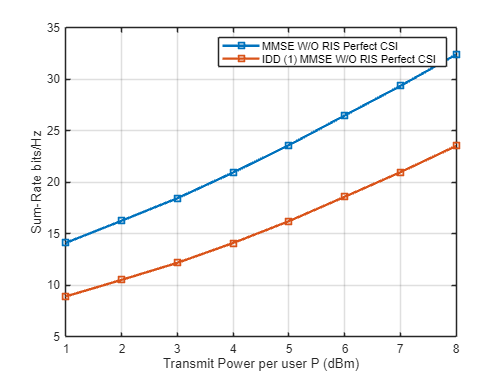

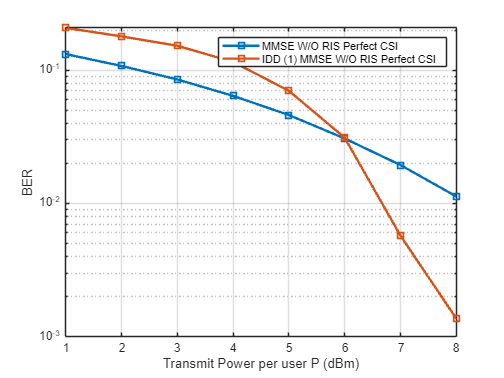

generatePlots(methods, Pw_user_dBm,BerVec,RsumVec,0)

if ~useParallel
    close(f);
end
